# Homework #1

ME599 Data Analysis

Aaron Cornelius

2020-9-3

# NOTE: EMAIL IT TO HIM

Note: the code used to generate all figures and output in this document is included immediately adjacent to the figure/output.

### 1. Determine the period of the function defined by $x\left(t\right)=\sin \;11t+\sin \;12t$ 

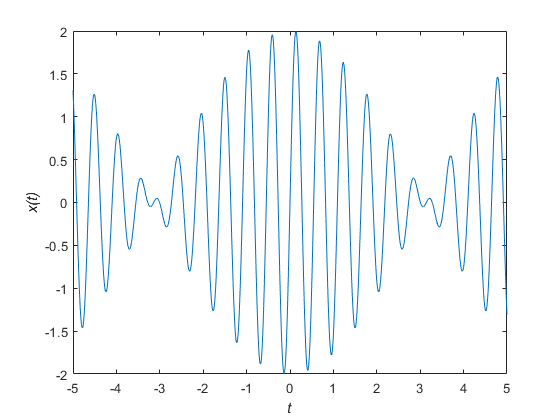

warning('off')
f = @(t) sin(11*t) + sin(12*t);
figure
fplot(f, [-5 5])
xlabel('\it{t}')
ylabel('\it{x(t)}')

There are two main methods of finding the period of this function. Both will be demonstrated. First, we can find the highest common frequency divisor for the two frequencies $\frac{11}{2\pi \;},\frac{12}{2\pi \;}$, and then calculate the period of that frequency. Once that is calculated, the frequency will be inverted to find the period (truncated here to three significant digits.)

f_common = 1/(2*pi) * gcd(11, 12);
disp(['The period of this function is: ' num2str(1/f_common, 3)])

The period of this function is: 6.28


This agrees with visual inspection of the graph. The other main method is to find the least common multiple of the periods $\frac{2\pi \;}{11},\frac{2\pi \;}{12}$. This method is generally more robust, since finding common divisors for non-integer values can be difficult. For this function, that can be found easily: $\frac{2\pi \;}{11}\cdot 11=\frac{2\pi \;}{12}\cdot 12=2\pi$. A generalizable function is defined for the remaining problems.

calcPeriod = @(periods) lcm(sym(periods));
period = calcPeriod([2*pi/11, 2*pi/12])

$$period = 2\,\pi$$

Since $2\pi$ is equivalent to `6.28` to three significant figures, both methods found the same answer. This is the method that will be used going forward.

### 2. For the following functions, which are periodic and which are non-periodic?

#### (a) $x\left(t\right)=3\;\sin \;t+2\;\sin \;2t+\sin \;3t$

This function is periodic, since all three ratios of the angular velocities are rational: $\frac{1}{2},\frac{1}{3},\frac{2}{3}$.

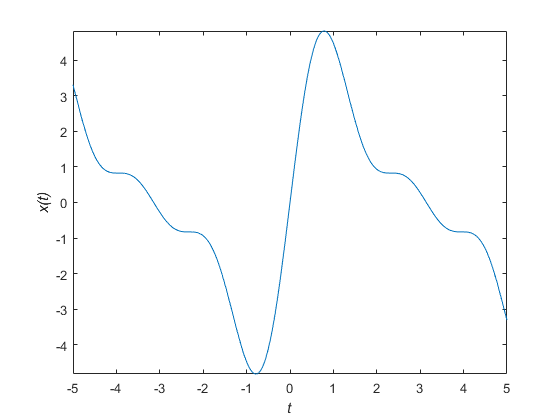

f = @(t)3*sin(t) + 2*sin(2*t)+sin(3*t);
figure
fplot(f, [-5, 5])
xlabel('\it{t}')
ylabel('\it{x(t)}')

The period is calculated as the least common multiple of the periods of each of the subfunctions: $2\pi \;,\frac{2\pi \;}{2},\frac{2\pi \;}{3}$.

period = calcPeriod([2*pi, 2*pi/2, 2*pi/3])

$$period = 2\,\pi$$

This agrees with a visual inspection of the chart: it visually appears to have roughly one period over $t=-4$ to $t=2$, which is close to a period of $2\pi \ldotp$

#### (b) $x\left(t\right)=3\;\sin \;t+2\;\sin \;2t+\sin \;\pi t$

This function is not periodic. This can be seen by calculating the ratio of either the first or second term's angular velocity to the third term's angular velocity: $\frac{1}{\pi \;}$ or $\frac{2}{\pi \;}$. These ratios are not rational, and therefore the function is not periodic. This is not possible to confirm via visual inspection, since it could repeat with a period longer than is being currently viewed.

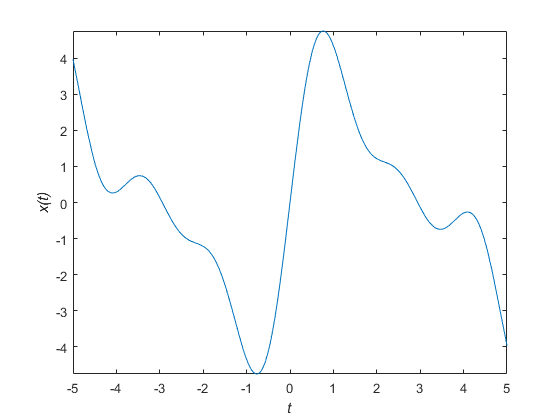

f = @(t)3*sin(t) + 2*sin(2*t)+sin(pi*t);
figure
fplot(f, [-5, 5])
xlabel('\it{t}')
ylabel('\it{x(t)}')

#### (c) $x\left(t\right)=3\;\sin \;4t+2\;\sin \;5t+\sin \;6t$

This function is periodic. All the ratios between the different angular velocities are rational: $\frac{4}{5},\frac{4}{6},\frac{5}{6}$. 

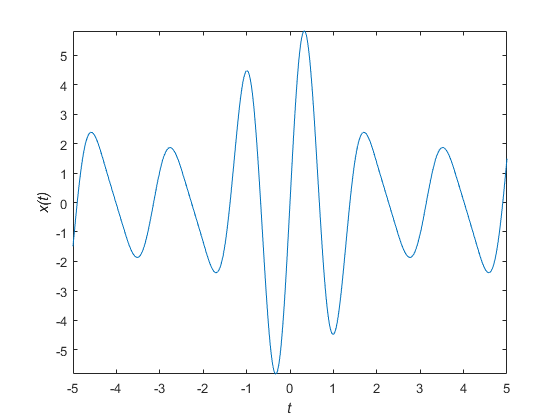

f = @(t)3*sin(4*t) + 2*sin(5*t)+sin(6*t);
figure
fplot(f, [-5, 5])
xlabel('\it{t}')
ylabel('\it{x(t)}')

The period is calculated as the least common multiple of the periods of each of the subfunctions: $\frac{2\pi }{4}\;,\frac{2\pi \;}{5},\frac{2\pi \;}{6}$.

period = calcPeriod([2*pi/4, 2*pi/5, 2*pi/6])

$$period = 2\,\pi$$

This matches up with a visual inspection of the chart: it visually appears to have roughly one period over $t=-2\ldotp 8$ to $t=3\ldotp 5$, which is close to a period of $2\pi \ldotp$

#### (d) $x\left(t\right)=e^{-t} \;\sin \;t$

This function is not periodic due to the exponential term, which will never repeat, and instead decays exponentially. This is not possible to confirm via visual inspection, since it could repeat with a period longer than is being currently viewed.

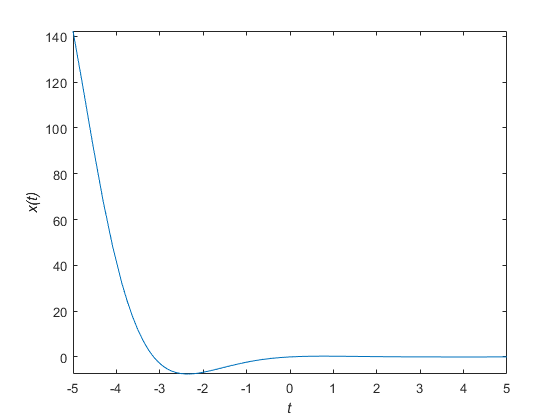

f = @(t)exp(-t).*sin(t);
figure
fplot(f, [-5, 5])
xlabel('\it{t}')
ylabel('\it{x(t)}')

### 3. Determine if $x\left(t\right)=\sin \left(\sqrt{50}t\right)+4\;\cos \left(\sqrt{\;98}t-\frac{\;\pi \;}{4}\right)$is periodic, and if so, what is its period?

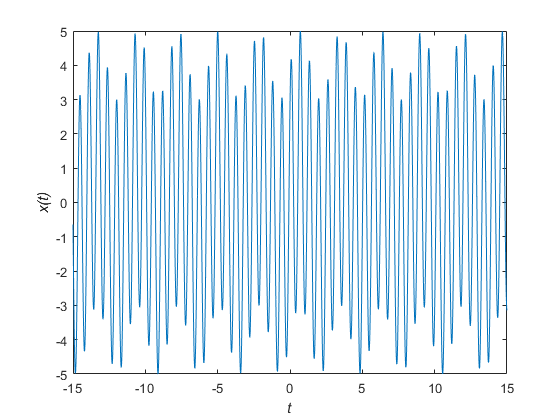

f = @(t)sin(sqrt(5)*t)+4*cos(sqrt(98)*t-pi/4);
figure
fplot(f, [-15, 15])
xlabel('\it{t}')
ylabel('\it{x(t)}')

This function is periodic. This can be seen by comparing the ratio of the two angular velocities: $\frac{\sqrt{\;50}}{\sqrt{\;98}}=\frac{\sqrt{\;2}}{\sqrt{\;2}}\cdot \frac{\sqrt{\;25}}{\sqrt{\;49}}=\frac{5}{7}$. Since this is a rational number, it means that the function is periodic.

The period is calculated as the least common multiple of the periods of each of the subfunctions: $\frac{2\pi \;}{\sqrt{\;50}},\frac{2\pi \;}{\sqrt{\;98}}$. The fact that one of the functions is offset (via both the cosine vs sine function and by subtracting $\frac{\pi }{4}$) is irrelevant. 

period = calcPeriod([1/sqrt(5), 1/sqrt(98)])*2*pi

$$period = 2\,\pi \,\sqrt{2}\,\sqrt{5}$$

Evaluated, this comes out to:

2*pi*sqrt(2)*sqrt(5)

ans = 19.8692

This agrees with a visual inspection of the chart: it visually appears to have roughly one period over $t=-13\ldotp 5$ to $t=6\ldotp 5$.

### 4. Calculate the Fourier Transform $X\left(\omega \;\right)$ of the following function and plot $X\left(\omega \right)$ in the complex plane. Graph the magnitude $\left|X\left(\omega \;\right)\right|$ and phase $\angle X\left(\omega \;\right)$ with $A=2,a=1,b=\pi$ for $0\le \omega \le 10$.


$$x\left(t\right)=\left\lbrace \begin{array}{ll}
{\textrm{Ae}}^{-\textrm{at}} \;\cos \;\textrm{bt} & t\ge 0\\
0 & t<0
\end{array}\right.$$


The Fourier transform can be defined as:


$$X\left(\omega \right)=\int_{-\infty }^{\infty } x\left(t\right)\cdot e^{-j\omega \;t} \;\textrm{dt}$$


For this specific formula, that can be written:


$$X\left(\omega \;\right)=\int_0^{\infty } A\;e^{-\textrm{at}} \;\cos \;\textrm{bt}\cdot e^{-j\omega \;t} \;\textrm{dt}=A\int_0^{\infty } \;e^{-t\;\left(a+j\omega \;\right)} \;\cos \;\textrm{bt}\;\textrm{dt}$$


From an integral table, it is known that the following is true (coefficents have been re-labeled to avoid overlap with the problem definition):


$$\int \;e^{B\;x} \;\cos \;C\;x\;\textrm{dx}=\frac{\;1}{B^2 +C^2 }e^{B\;x} \left(B\;\sin \;C\;x+B\;\cos \;C\;x\right)$$


For this problem, $B=-a-j\omega \;,\;C=b,\;x=t$. Therefore:


$$X\left(\omega \;\right)=A{\left(\frac{\;\left(-a-j\;\omega \right)}{{\left(-a-j\omega \;\right)}^2 +b^2 }e^{t\left(-a-j\omega \right)} \left(\sin \;b\;t+\cos \;b\;t\right)\right)\left|\right.}_0^{\infty } \;$$


This can be further simplifed due to the fact that $e^0 =1,\sin \left(0\right)=0,\cos \left(0\right)=1$, and for any positive value of $a$, $e^{-a\cdot \;\infty } =0$:


$$X\left(\omega \;\right)=A\left(\frac{\;\left(-a-j\;\omega \right)}{{\left(-a-j\omega \;\right)}^2 +b^2 }\cdot 0\cdot \;\left(\sin \;b\;\infty +\cos \;b\;\infty \right)\right){-A\left(\frac{\;\left(-a-j\;\omega \right)}{{\left(-a-j\omega \;\right)}^2 +b^2 }\cdot 1\cdot \;\left(0+1\right)\right)\left|\right.}_0^{\infty }$$



$$\Rightarrow X\left(\omega \;\right)=\left(\frac{\;\left(-a-j\;\omega \right)}{{\left(-a-j\omega \;\right)}^2 +b^2 }e^{\infty \left(-a-j\omega \right)} \left(\sin \;b\;\infty +\cos \;b\;\infty \right)\right){-\left(\frac{\;\left(-a-j\;\omega \right)}{{\left(-a-j\omega \;\right)}^2 +b^2 }e^{0\left(-a-j\omega \right)} \left(\sin \;b\;0+\cos \;b\;0\right)\right)\left|\right.}_0^{\infty }$$



$$\Rightarrow X\left(\omega \;\right)=A\frac{a+j\omega }{{\left(a+j\omega \;\right)}^2 +b^2 }$$


Unfortuntately, it does not appear to be possible simplify this further and eliminate the $j$ value on the bottom. The Fourier transform will now be graphed in the complex plane:

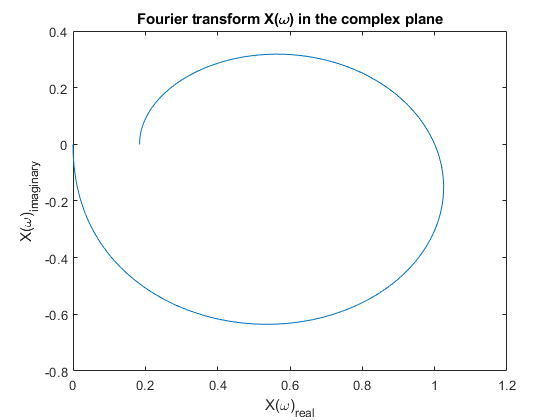

XFourier = @(omega)2.*(1+1i.*omega)./((1+1i.*omega).^2+pi^2);
vals = XFourier(0:0.01:2000);
figure
plot(vals)
xlabel('X(\omega)_{real}')
ylabel('X(\omega)_{imaginary}')
title('Fourier transform X(\omega) in the complex plane')

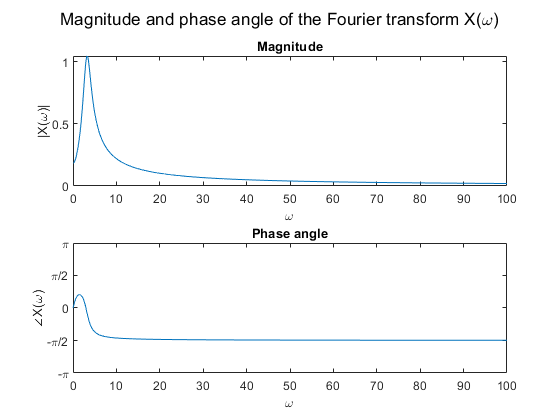

figure
subplot(2,1,1)
plot(0:0.01:2000, abs(vals))
xlim([0, 100])
xlabel('\omega')
ylabel('|X(\omega)|')
title('Magnitude')
subplot(2,1,2)
plot(0:0.01:2000, angle(vals))
xlim([0 100])
xlabel('\omega')
ylabel('\angle{X(\omega)}')
yticks([-pi -pi/2 0 pi/2 pi])
yticklabels(["-\pi" "-\pi/2" "0" "\pi/2" "\pi"])
ylim([-pi pi])
title('Phase angle')
sgtitle('Magnitude and phase angle of the Fourier transform X(\omega)')

### 5. Determine the Fourier series approximation of the following sawtooth wave and plot the results with $n=1,3,5,15,95$ on the same figure. In your graph, show the results from $0\le t\le 2$, and use at least 10000 points to resolve the edge effects. Based on your observations, what do you think the spectrum of a sawtooth wave would look like compared to a sine wave at the same frequency?

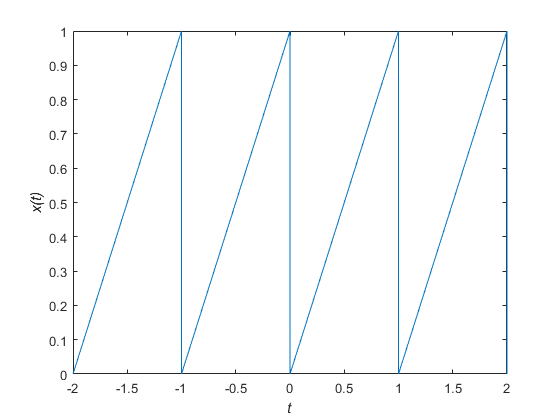

figure
xFunc = @(t)t-floor(t);
assert(all([xFunc(0.5)==0.5, xFunc(1.5)==0.5]));
fplot(xFunc, [-2, 2])
xlabel('{\it{t}}')
ylabel('{\it{x(t)}}')

By examining the plot, it is obvious that the function has a period of 1. Therefore, the lowest eigenvalue for the Fourier series is $\lambda {\;}_1 =1\cdot 2\pi =2\pi \;$, and the other eigenvalues are formed at integer multiples of that: $\lambda_n =n\cdot 2\pi$ for $n=1,2,3\ldotp \ldotp \ldotp$ This can be implemented in code as:

lambda_n = @(n) 2 .* pi .* n;
assert(lambda_n(2) == 4*pi);

Once the lambda values are known, the Fourier series coefficients can be calculated. $a_0 ,a_n ,b_n$ only need to be evaluated over one period of the function. This means the sawtooth behavior caused by the floor function can be ignored for the calculation of the coefficients. Therefore, the coefficients can be calculated by evalulating:


$$a_0 =\int_0^1 t\;\textrm{dt},a_n =2\int_0^1 t\;\cos \left(\lambda {\;}_n \;t\right)\;\textrm{dt},b_n =2\int_0^1 t\;\sin \left(\lambda {\;}_n \;t\right)\;\textrm{dt}$$


$a_0$ is simple to evaluate: 


$$a_0 =\int_0^1 t\;\textrm{dt}=0\ldotp 5\left(t^2 \right){\left|\right.}_0^1 =0\ldotp 5\left(1-0\right)=0\ldotp 5$$


$a_n$ can be evaluated by using the following from an integral table:


$$\int \;x\;\cos \;\textrm{ax}\;\textrm{dx}=\frac{1}{a^2 }\cos \;\textrm{ax}+\frac{x}{a}\sin \;\textrm{ax}$$


Therefore:


$$a_n =2\int_0^1 t\;\cos \left(\lambda {\;}_n \;t\right)\;\textrm{dt}=2\left(\frac{1}{\lambda {\;}_n^2 }\cos \;\lambda_n +\frac{1}{\lambda_n }\sin \;\lambda_n \right)-2\left(\frac{1}{\lambda {\;}_n^2 }\cos \;0+\frac{0}{\lambda_n }\sin \;0\right)=2\left(\frac{1}{\lambda {\;}_n^2 }\cos \;\lambda_n +\frac{1}{\lambda_n }\sin \;\lambda_n \right)-\frac{2}{\lambda {\;}_n^2 }$$


Since $\lambda_n$ is always a multiple of $2\pi$, it follows that $\cos \;\lambda_n =1,\sin \;\lambda {\;}_n =0$ for any value of $\lambda_n$. Therefore:


$$a_n =\frac{2}{\lambda {\;}_n^2 }-\frac{2}{\lambda {\;}_n^2 }=0$$


This makes intuitive sense: $x\left(t\right)$ is purely odd (i.e. $f\left(x\right)=-f\left(-x\right)$), and cosine terms describe the even portions of functions (i.e. $f\left(x\right)=f\left(-x\right)$.) Therefore, all the cosine weighting terms should be zero.

Finally, $b_n$ can be calculated using the following property from an integral table:


$$\int x\;\sin \;\textrm{ax}\;\textrm{dx}=-\frac{\;x\;\cos \;\textrm{ax}}{a}+\frac{\;\sin \;\textrm{ax}}{a^2 }$$


Therefore:


$$b_n =2\int_0^1 t\;\sin \left(\lambda {\;}_n \;t\right)\;\textrm{dt}=-2\left(\frac{\cos \;\lambda_n }{\lambda_n }+\frac{\;\sin \;\lambda_n }{\lambda_n }\right)+\frac{\;0\;\cos \;0}{\lambda_n }-\frac{\;2\;\sin \;0}{\lambda_n }=-2\left(\frac{\;\cos \;\lambda_n }{\lambda_n }+\frac{\;\sin \;\lambda_n }{\lambda_n }\right)$$


Again, the fact that $\lambda_n$ is always a multiple of $2\pi$ can be exploited:


$${\Rightarrow \;b}_n =\int_0^1 t\;\sin \left(\lambda {\;}_n \;t\right)\;\textrm{dt}=-\frac{\;2}{\lambda_n }=-\frac{1}{n\pi \;}$$


As a result, the full formula for the Fourier series can be written as $x\left(t\right)=0\ldotp 5-\sum_{n=1}^{\infty } \frac{1}{n\pi \;}\sin \left(2n\pi \cdot t\right)$, and the approximate formula for $k$ eigenvalues is:

$\tilde{x} \left(t,k\right)=0\ldotp 5-\sum_{n=1}^k \frac{1}{n\pi \;}\sin \left(2n\pi \cdot t\right)$.

This can therefore be plotted for different numbers of eigenvalues to compare the accuracy of the Fourier series approximation.

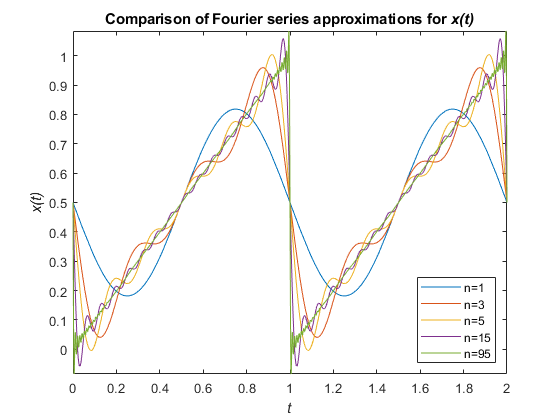

xFourier = @(k, x) (0.5 - sum(sin(2*pi*([1:k]') .* x) .* (1./(pi*[1:k]'))));

% Plot values
figure
fplot(@(x) xFourier(1,x), [0, 2]) % n=1
hold on
fplot(@(x) xFourier(3,x), [0, 2]) % n=3
fplot(@(x) xFourier(5,x), [0, 2]) % n=5
fplot(@(x) xFourier(15,x), [0, 2]) % n=15
fplot(@(x) xFourier(95,x), [0, 2]) % n=95
legend(["n=1" "n=3" "n=5" "n=15" "n=95"], 'location', 'southeast')
xlabel('\it{t}')
ylabel('\it{x(t)}')
title('Comparison of Fourier series approximations for {\it{x(t)}}')

Now the coefficients are plotted against their frequencies to more intuitively display the frequency pattern for a saw-tooth wave. Under most circumstances, the real and imaginary components (or the magnitude and phase angle) would have to be plotted seperately. However, it has already been proven that only the sine coefficients $b_n$ are non-zero: therefore, the cosine coefficients are omitted.

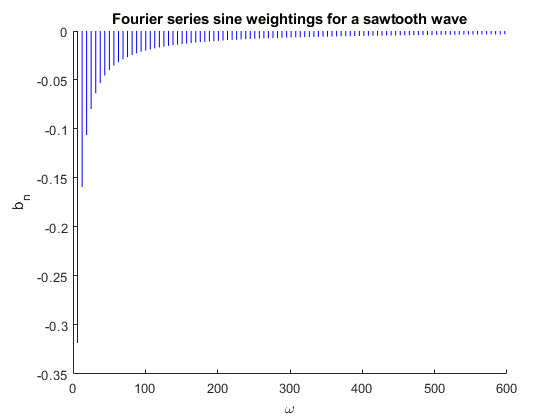

figure
clf
hold on
for i = 1:95
    plot([2*pi*i 2*pi*i], [0, -1/(pi*i)], 'color', 'blue')
    b_n=-1/(pi*i);
    omega = 2*pi*i;
end
xlabel('\omega')
ylabel('b_n')
title('Fourier series sine weightings for a sawtooth wave')

Since all sawtooth-form waves are purely odd functions, all of them will solely have sine coefficients. As shown in the figure above, the Fourier series coefficients correspond to an exponentially decreasing function of the form $b_n \propto \frac{1}{\omega \;}$. The exact shape of these coefficients will depend on the shape of the waveform: for example, if the "teeth" of the sawtooth waveform are angled the other way the coefficients will be positive rather than negative. However, the basic form will apply to any sawtooth wave.